# SPEAR3 HVPS Analytical Design Math Technical Notebook

This notebook is a standalone technical note for the SPEAR3 legacy high-voltage power supply. It converts the analytical design math from the HVPS design report into executable calculations, engineering tables, and plots that show how the system behaves from the three-phase AC input through rectification, filtering, protection, and klystron loading.

Notebook objectives: - Recreate the 3-phase to 12-pulse rectifier waveform construction - Verify the documented DC output and firing-angle relationships - Quantify ripple, filtering, beam current, protection energy, power quality - Add an engineering ramp-up model from 0 kV to the 77 kV operating point - Generate representative versions of the four B118 monitoring channels

## System Overview and Governing Equations

The legacy SPEAR3 HVPS is a 12-pulse controlled rectifier system that converts 12.47 kV, 60 Hz three-phase utility power into a regulated negative cathode supply for the klystron. The physical conversion chain:


$$12.47\;\mathrm{kV}_{LL,\;rms}\;3\phi \rightarrow T_0\;(\pm 15^\circ) \rightarrow T_1,T_2 \rightarrow 2\times 6\text{-pulse bridges} \rightarrow 12\text{-pulse DC} \rightarrow LC\;\text{filter} \rightarrow -77\;\mathrm{kV}\;\text{to klystron}$$


**Three-phase to line-line conversion:**


$$v_a = V_m\sin(\omega t), \quad v_b = V_m\sin(\omega t - 120^\circ), \quad v_c = V_m\sin(\omega t + 120^\circ)$$



$$v_{ab} = v_a - v_b = \sqrt{2}\,V_{LL}\cos(\omega t - 60^\circ)$$


**Average 12-pulse DC output:**


$$V_{dc} = \frac{6\sqrt{2}}{\pi}\,V_{LL}\cos\alpha \approx 2.70\,V_{LL}\cos\alpha$$


**Klystron beam-current model (Child-Langmuir perveance):**


$$I_{beam} = P_k\,V_{cathode}^{3/2}$$


**Ripple and filter estimates:**


$$\frac{\Delta V_{pp}}{V_{max}} = 1 - \cos(15^\circ), \qquad f_{ripple} = 12\,f_{line} = 720\;\mathrm{Hz}$$


**Stored-energy expressions used in the protection analysis:**


$$E_C = \frac{1}{2}CV^2, \qquad E_L = \frac{1}{2}LI^2$$


## System Block Diagram Mapped to Equation Sections

This figure ties the physical HVPS subsystems to the analytical sections. Each block maps to a part of the power-conversion chain and the associated governing equations developed in later sections.

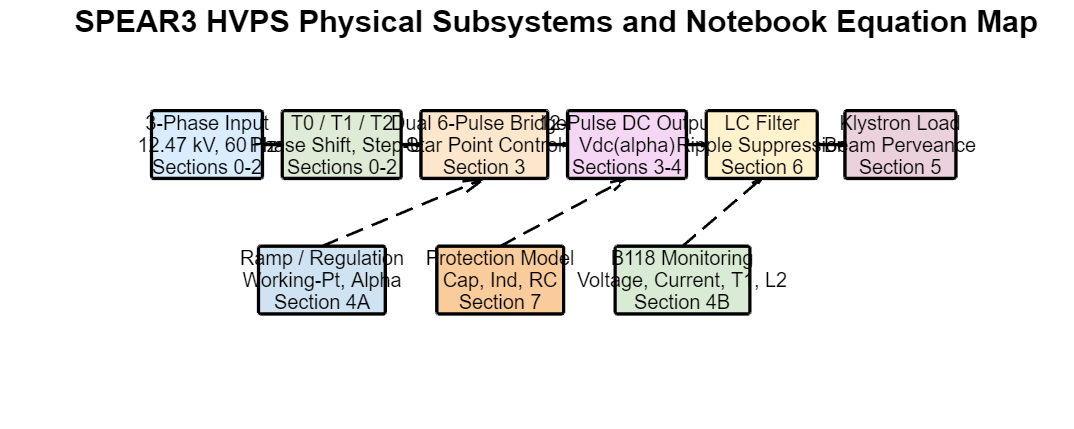

figure('Position', [50 50 1500 600]);
hold on; axis off;
xlim([0 21]); ylim([0 8]);

% --- Top row: main power-conversion chain ---
%  Block:  x0    y0    w     h     label lines                                         color
blocks = {
    0.3,  4.8,  2.8,  1.6,  {'3-Phase Input','12.47 kV, 60 Hz','Sections 0-2'},      [0.85 0.93 1.0];   % 1
    3.6,  4.8,  3.0,  1.6,  {'T0 / T1 / T2','Phase Shift, Step-Up','Sections 0-2'},   [0.87 0.92 0.84];  % 2
    7.1,  4.8,  3.2,  1.6,  {'Dual 6-Pulse Bridges','Star Point Control','Section 3'}, [0.99 0.90 0.80];  % 3
   10.8,  4.8,  3.0,  1.6,  {'12-Pulse DC Output','Vdc(alpha)','Sections 3-4'},        [0.96 0.84 0.96];  % 4
   14.3,  4.8,  2.8,  1.6,  {'LC Filter','Ripple Suppression','Section 6'},            [1.0  0.95 0.80];  % 5
   17.8,  4.8,  2.8,  1.6,  {'Klystron Load','Beam Perveance','Section 5'},            [0.92 0.82 0.86];  % 6
% --- Bottom row: support / monitoring ---
    3.0,  1.6,  3.2,  1.6,  {'Ramp / Regulation','Working-Pt, Alpha','Section 4A'},    [0.81 0.89 0.95];  % 7
    7.5,  1.6,  3.2,  1.6,  {'Protection Model','Cap, Ind, RC','Section 7'},           [0.98 0.80 0.61];  % 8
   12.0,  1.6,  3.4,  1.6,  {'B118 Monitoring','Voltage, Current, T1, L2','Section 4B'},[0.85 0.92 0.83]; % 9
};
for k = 1:size(blocks,1)
    x0 = blocks{k,1}; y0 = blocks{k,2};
    w  = blocks{k,3};  h  = blocks{k,4};
    lbl = blocks{k,5}; clr = blocks{k,6};
    rectangle('Position',[x0 y0 w h],'FaceColor',clr,'EdgeColor','k','LineWidth',1.5,'Curvature',0.05);
    text(x0+w/2, y0+h/2, lbl, 'HorizontalAlignment','center','VerticalAlignment','middle','FontSize',9);
end

% --- Horizontal arrows between top-row blocks (right edge -> left edge) ---
%  From block edges:  1 right=3.1  2 left=3.6  2 right=6.6  3 left=7.1
%                     3 right=10.3 4 left=10.8 4 right=13.8 5 left=14.3
%                     5 right=17.1 6 left=17.8
y_top_mid = 4.8 + 1.6/2;   % vertical center of top-row blocks = 5.6
arrows_h = [3.1 y_top_mid 3.6 y_top_mid; ...
            6.6 y_top_mid 7.1 y_top_mid; ...
           10.3 y_top_mid 10.8 y_top_mid; ...
           13.8 y_top_mid 14.3 y_top_mid; ...
           17.1 y_top_mid 17.8 y_top_mid];
for k = 1:size(arrows_h,1)
    dx = arrows_h(k,3) - arrows_h(k,1);
    dy = arrows_h(k,4) - arrows_h(k,2);
    quiver(arrows_h(k,1), arrows_h(k,2), dx, dy, 0, 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.8);
end

% --- Vertical dashed arrows from bottom-row blocks up to top-row blocks ---
%  Ramp/Regulation (block 7, center_x=4.6, top=3.2) --> Dual 6-Pulse (block 3, center_x=8.7, bottom=4.8)
%  Protection Model (block 8, center_x=9.1, top=3.2) --> 12-Pulse DC (block 4, center_x=12.3, bottom=4.8)
%  B118 Monitoring  (block 9, center_x=13.7, top=3.2) --> LC Filter  (block 5, center_x=15.7, bottom=4.8)
vert_arrows = [4.6 3.2  8.7  4.8; ...    % Ramp -> Dual 6-Pulse
               9.1 3.2 12.3  4.8; ...    % Protection -> 12-Pulse DC
              13.7 3.2 15.7  4.8];        % B118 -> LC Filter
for k = 1:size(vert_arrows,1)
    dx = vert_arrows(k,3) - vert_arrows(k,1);
    dy = vert_arrows(k,4) - vert_arrows(k,2);
    quiver(vert_arrows(k,1), vert_arrows(k,2), dx, dy, 0, ...
        'k', 'LineWidth', 1.2, 'LineStyle', '--', 'MaxHeadSize', 0.4);
end

title('SPEAR3 HVPS Physical Subsystems and Notebook Equation Map','FontSize',14,'FontWeight','bold');

## 1. System Constants and Helper Functions

The report uses a 12.47 kV, 60 Hz input, a 33.3 kV secondary line-to-line voltage, a 90 kV maximum DC output, and a nominal operating point near 77 kV. This cell defines the shared constants and helper functions.

DEG = pi / 180.0;

% System constants (struct equivalent of Python dict)
sys.f_line_hz                       = 60.0;
sys.v_input_ll_rms                  = 12.47e3;
sys.v_t1_primary_ll_rms             = 12.5e3;
sys.v_secondary_ll_rms              = 33.3e3;
sys.vdc_max                         = 90.0e3;
sys.vdc_nominal                     = 77.0e3;
sys.idc_nominal                     = 22.0;
sys.vdc_measured                    = 72.08e3;
sys.idc_measured                    = 19.4;
sys.cap_filter_f                    = 8e-6;
sys.isolation_res_ohm               = 500.0;
sys.inductor_primary_h              = 0.3;
sys.inductor_primary_rated_a        = 85.0;
sys.cable_inductor_h                = 200e-6;
sys.power_factor_distortion_12pulse = 0.9886;

## 2. Three-Phase Input and Six Line-to-Line Voltages

The derivation starts with the three phase voltages:


$$v_a = V_m\sin(\omega t), \quad v_b = V_m\sin(\omega t - 120^\circ), \quad v_c = V_m\sin(\omega t + 120^\circ)$$


and constructs the six line-to-line voltages that a 6-pulse bridge selects from (e.g. $v_{ab} = v_a - v_b$). The plot shows one electrical cycle at the 33.3 kV secondary level.

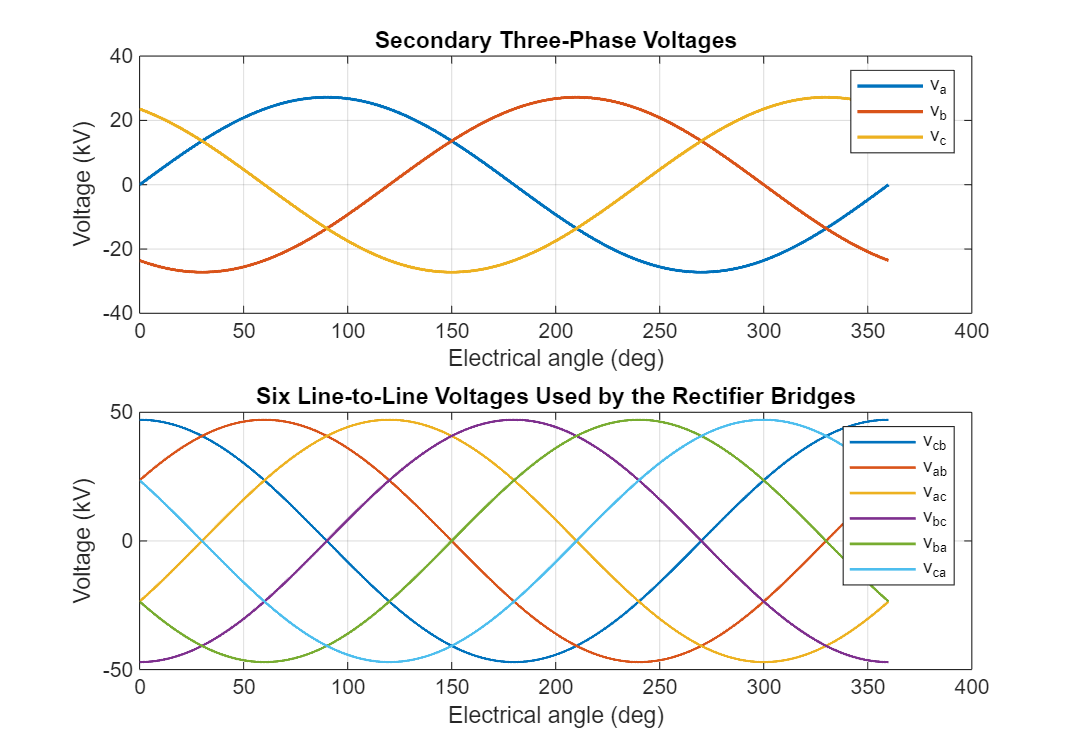

theta = linspace(0, 2*pi, 4000);
theta_deg_vec = rad2deg(theta);
v_phase_rms  = sys.v_secondary_ll_rms / sqrt(3);
v_phase_peak = sqrt(2) * v_phase_rms;

va = v_phase_peak .* sin(theta);
vb = v_phase_peak .* sin(theta - 2*pi/3);
vc = v_phase_peak .* sin(theta + 2*pi/3);

v_cb = vc - vb;  v_ab = va - vb;  v_ac = va - vc;
v_bc = vb - vc;  v_ba = vb - va;  v_ca = vc - va;

figure('Position', [100 100 1000 700]);
subplot(2,1,1);
plot(theta_deg_vec, va/1e3, theta_deg_vec, vb/1e3, theta_deg_vec, vc/1e3, 'LineWidth', 1.5);
title('Secondary Three-Phase Voltages');
xlabel('Electrical angle (deg)'); ylabel('Voltage (kV)');
legend('v_a','v_b','v_c'); grid on;

subplot(2,1,2);
plot(theta_deg_vec, v_cb/1e3, theta_deg_vec, v_ab/1e3, theta_deg_vec, v_ac/1e3, ...
     theta_deg_vec, v_bc/1e3, theta_deg_vec, v_ba/1e3, theta_deg_vec, v_ca/1e3, 'LineWidth', 1.2);
title('Six Line-to-Line Voltages Used by the Rectifier Bridges');
xlabel('Electrical angle (deg)'); ylabel('Voltage (kV)');
legend('v_{cb}','v_{ab}','v_{ac}','v_{bc}','v_{ba}','v_{ca}'); grid on;

## 3. Single 6-Pulse Bridge Envelope and Two-Bridge 12-Pulse Combination

Bridge X selects the highest of six cosine-shifted line-line waveforms, creating the familiar $60^\circ$ envelope segments. Bridge Y is shifted by $30^\circ$, and the two bridge outputs sum in series to create the 12-pulse waveform:


$$V_{bridge}(\theta) = \max_k \left\{ \sqrt{2}\,V_{LL}\cos\!\left(\theta - \frac{k\pi}{3}\right) \right\}, \quad k = 0,1,\ldots,5$$



$$V_{12\text{-pulse}} = V_{bridge,X}(\theta) + V_{bridge,Y}(\theta - 30^\circ)$$


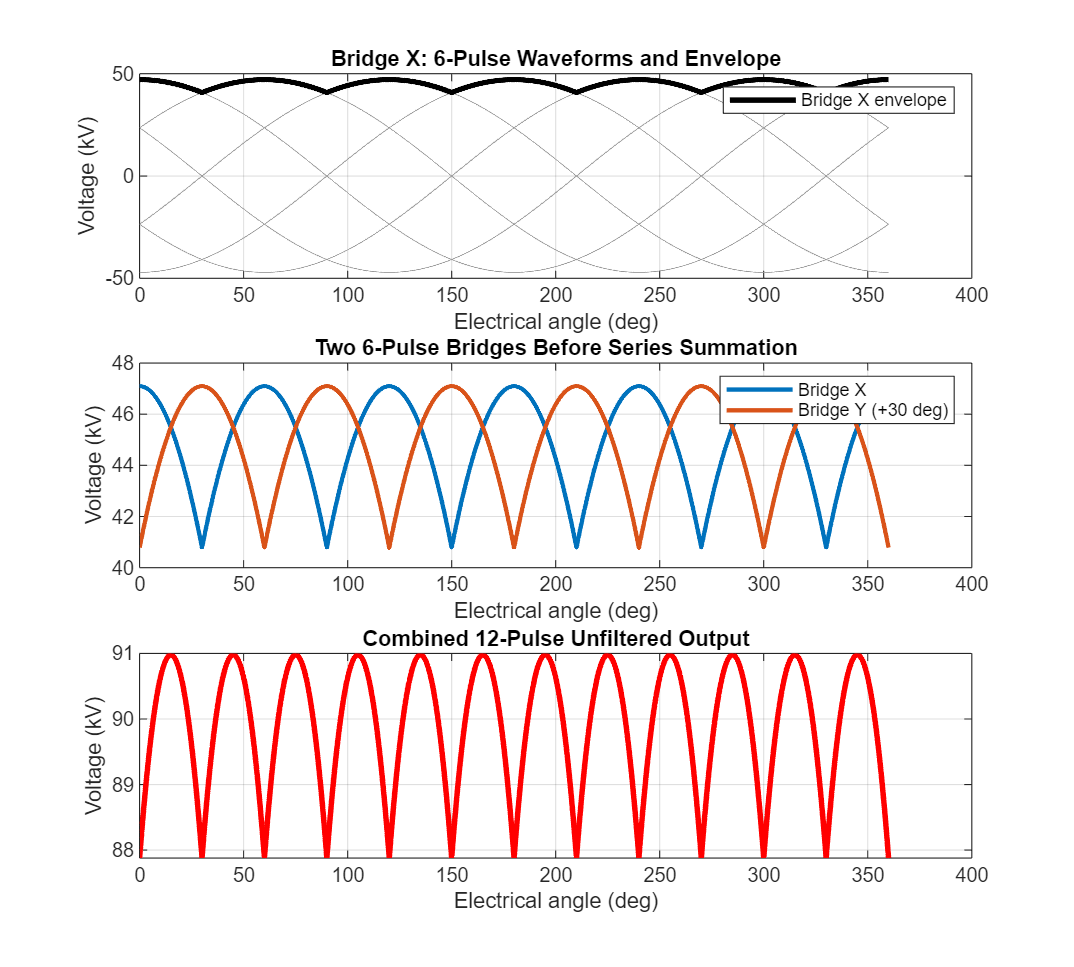

% --- 6-pulse bridge helper (inline) ---
% Generates six cosine waveforms and takes the max (envelope)
phases_x_deg = [0 60 120 180 240 300];
bridge_x_waves = zeros(6, length(theta));
for idx = 1:6
    bridge_x_waves(idx,:) = sqrt(2)*sys.v_secondary_ll_rms .* cos(theta - phases_x_deg(idx)*DEG);
end
bridge_x_env = max(bridge_x_waves, [], 1);

phases_y_deg = phases_x_deg + 30;
bridge_y_waves = zeros(6, length(theta));
for idx = 1:6
    bridge_y_waves(idx,:) = sqrt(2)*sys.v_secondary_ll_rms .* cos(theta - phases_y_deg(idx)*DEG);
end
bridge_y_env = max(bridge_y_waves, [], 1);

bridge_sum = bridge_x_env + bridge_y_env;

figure('Position', [100 100 1000 900]);
subplot(3,1,1);
for idx = 1:6
    plot(theta_deg_vec, bridge_x_waves(idx,:)/1e3, 'Color', [0.6 0.6 0.6]); hold on;
end
plot(theta_deg_vec, bridge_x_env/1e3, 'k', 'LineWidth', 2.5);
title('Bridge X: 6-Pulse Waveforms and Envelope');
xlabel('Electrical angle (deg)'); ylabel('Voltage (kV)');
legend('','','','','','','Bridge X envelope'); grid on;

subplot(3,1,2);
plot(theta_deg_vec, bridge_x_env/1e3, 'LineWidth', 2); hold on;
plot(theta_deg_vec, bridge_y_env/1e3, 'LineWidth', 2);
title('Two 6-Pulse Bridges Before Series Summation');
xlabel('Electrical angle (deg)'); ylabel('Voltage (kV)');
legend('Bridge X','Bridge Y (+30 deg)'); grid on;

subplot(3,1,3);
plot(theta_deg_vec, bridge_sum/1e3, 'r', 'LineWidth', 2.5);
title('Combined 12-Pulse Unfiltered Output');
xlabel('Electrical angle (deg)'); ylabel('Voltage (kV)'); grid on;

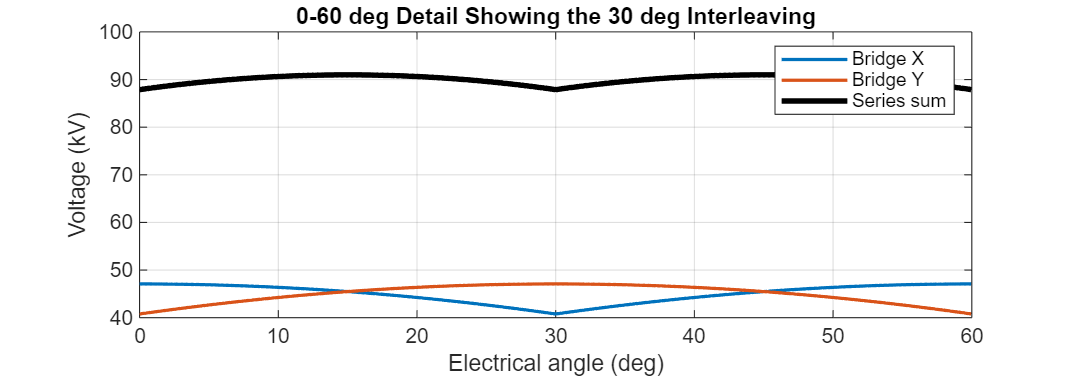


% 0-60 deg detail showing 30 deg interleaving
window = (theta_deg_vec >= 0) & (theta_deg_vec <= 60);
figure('Position', [100 100 1000 350]);
plot(theta_deg_vec(window), bridge_x_env(window)/1e3, 'LineWidth', 1.5); hold on;
plot(theta_deg_vec(window), bridge_y_env(window)/1e3, 'LineWidth', 1.5);
plot(theta_deg_vec(window), bridge_sum(window)/1e3, 'k', 'LineWidth', 2.5);
title('0-60 deg Detail Showing the 30 deg Interleaving');
xlabel('Electrical angle (deg)'); ylabel('Voltage (kV)');
legend('Bridge X','Bridge Y','Series sum'); grid on;

## 4. Average DC Output Versus Firing Angle

The report derives the 12-pulse DC average as:


$$V_{dc} = \frac{6\sqrt{2}}{\pi}\,V_{LL}\cos(\alpha)$$


This section verifies the nominal and measured operating points against that formula and visualizes the full firing-angle sweep.

alpha_deg_vec = linspace(0, 90, 721);
vdc_curve = (6*sqrt(2)/pi) .* sys.v_secondary_ll_rms .* cosd(alpha_deg_vec);

alpha_nom  = acosd(min(max(sys.vdc_nominal  / ((6*sqrt(2)/pi)*sys.v_secondary_ll_rms), -1), 1));
alpha_meas = acosd(min(max(sys.vdc_measured / ((6*sqrt(2)/pi)*sys.v_secondary_ll_rms), -1), 1));
turns_ratio = sys.v_secondary_ll_rms / sys.v_t1_primary_ll_rms;

% Operating points table
op_case   = {'Maximum'; 'Nominal'; 'Measured June 2020'};
op_vdc_kv = [sys.vdc_max/1e3; sys.vdc_nominal/1e3; sys.vdc_measured/1e3];
op_alpha  = [0.0; alpha_nom; alpha_meas];
op_cosalp = [1.0; cosd(alpha_nom); cosd(alpha_meas)];
operating_points = table(op_case, op_vdc_kv, op_alpha, op_cosalp, ...
    'VariableNames', {'Case','Vdc_kV','Alpha_deg','cos_alpha'});
disp(operating_points);

             Case             Vdc_kV    Alpha_deg    cos_alpha
    ______________________    ______    _________    _________

    {'Maximum'           }       90           0             1 
    {'Nominal'           }       77      31.117       0.85611 
    {'Measured June 2020'}    72.08      36.735       0.80141 



fprintf('Transformer turns ratio (secondary LL / primary LL): %.3f:1\n', turns_ratio);

Transformer turns ratio (secondary LL / primary LL): 2.664:1


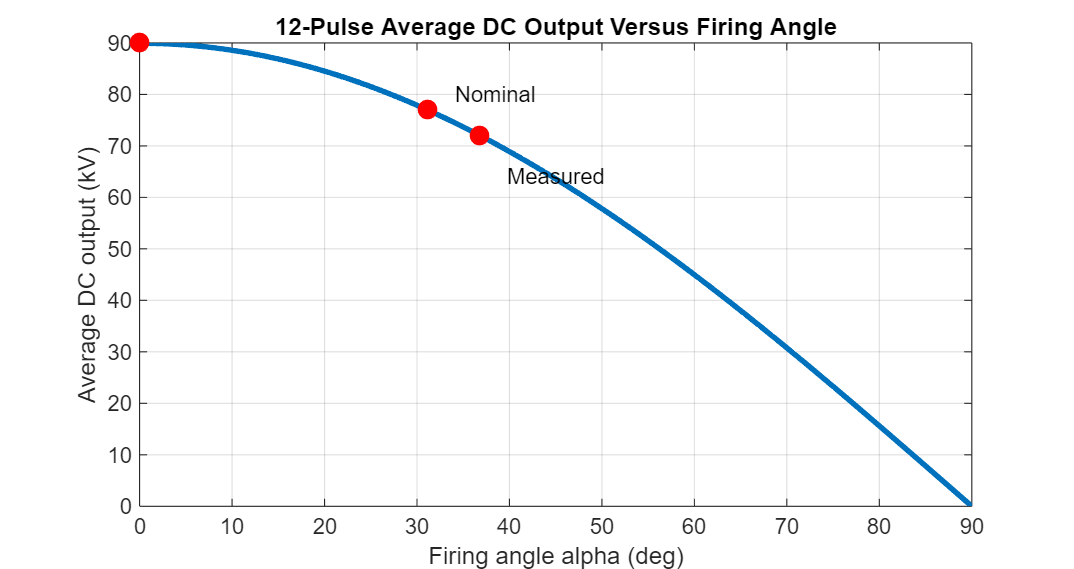


figure('Position', [100 100 850 450]);
plot(alpha_deg_vec, vdc_curve/1e3, 'LineWidth', 2.5); hold on;
scatter([0.0 alpha_nom alpha_meas], ...
        [sys.vdc_max/1e3 sys.vdc_nominal/1e3 sys.vdc_measured/1e3], 80, 'r', 'filled');
text(alpha_nom+3, sys.vdc_nominal/1e3+3, 'Nominal', 'FontSize', 10);
text(alpha_meas+3, sys.vdc_measured/1e3-8, 'Measured', 'FontSize', 10);
title('12-Pulse Average DC Output Versus Firing Angle');
xlabel('Firing angle alpha (deg)'); ylabel('Average DC output (kV)'); grid on;

## 4A. System Ramp-Up From 0 kV to the 77 kV Working Point

The control system ramps the output so that the cathode voltage, beam current, primary current, and control angle all move in a controlled way. The ramp model uses a smooth commanded voltage:


$$V_{cmd}(t) = V_{nom}\,s(t), \qquad s(t) = 3x^2 - 2x^3, \qquad x = \mathrm{clip}\!\left(\frac{t}{T_{ramp}},\;0,\;1\right)$$


From the commanded voltage, the implied firing angle and beam current are:


$$\alpha(t) = \cos^{-1}\!\left(\frac{V_{cmd}(t)}{V_{dc,max}}\right), \qquad I_{beam}(t) = P_k\,V_{cmd}(t)^{3/2}$$


t_ramp  = linspace(0, 30, 5000);
T_ramp  = 20.0;
x_ramp  = min(max(t_ramp / T_ramp, 0), 1);
smoothstep = 3*x_ramp.^2 - 2*x_ramp.^3;
vdc_ramp   = sys.vdc_nominal .* smoothstep;

% firing_angle_from_vdc
alpha_ramp = acosd(min(max(vdc_ramp ./ ((6*sqrt(2)/pi)*sys.v_secondary_ll_rms), -1), 1));

% beam_current_from_perveance
perveance = 1.0e-6;
beam_current_ramp = perveance .* (vdc_ramp.^1.5);
beam_power_ramp   = vdc_ramp .* beam_current_ramp / 1e6;

pf_ramp = max(cosd(alpha_ramp) .* sys.power_factor_distortion_12pulse, 0.15);
primary_current_ramp = zeros(size(vdc_ramp));
valid = pf_ramp > 0;
primary_current_ramp(valid) = (vdc_ramp(valid) .* beam_current_ramp(valid)) ./ ...
    (sys.v_t1_primary_ll_rms * sqrt(3) .* pf_ramp(valid));

% Ramp summary table
ramp_times = [0 5 10 15 20 30];
ramp_Vdc   = interp1(t_ramp, vdc_ramp, ramp_times) / 1e3;
ramp_Alpha = interp1(t_ramp, alpha_ramp, ramp_times);
ramp_Ibeam = interp1(t_ramp, beam_current_ramp, ramp_times);
ramp_Pbeam = interp1(t_ramp, beam_power_ramp, ramp_times);
ramp_Ipri  = interp1(t_ramp, primary_current_ramp, ramp_times);
ramp_table = table(ramp_times', ramp_Vdc', ramp_Alpha', ramp_Ibeam', ramp_Pbeam', ramp_Ipri', ...
    'VariableNames', {'Time_s','Vdc_kV','Alpha_deg','BeamCurrent_A','BeamPower_MW','PrimaryCurrent_A'});
disp(ramp_table);

    Time_s    Vdc_kV    Alpha_deg    BeamCurrent_A    BeamPower_MW    PrimaryCurrent_A
    ______    ______    _________    _____________    ____________    ________________

       0           0         90              0                 0                0     
       5      12.031     82.313         1.3197          0.015877            4.889     
      10        38.5     64.656         7.5542           0.29084           31.744     
      15      64.969     43.752          16.56            1.0759           69.587     
      20          77     31.117         21.367            1.6452           89.785     
      30          77     31.117         21.367            1.6452           89.785     



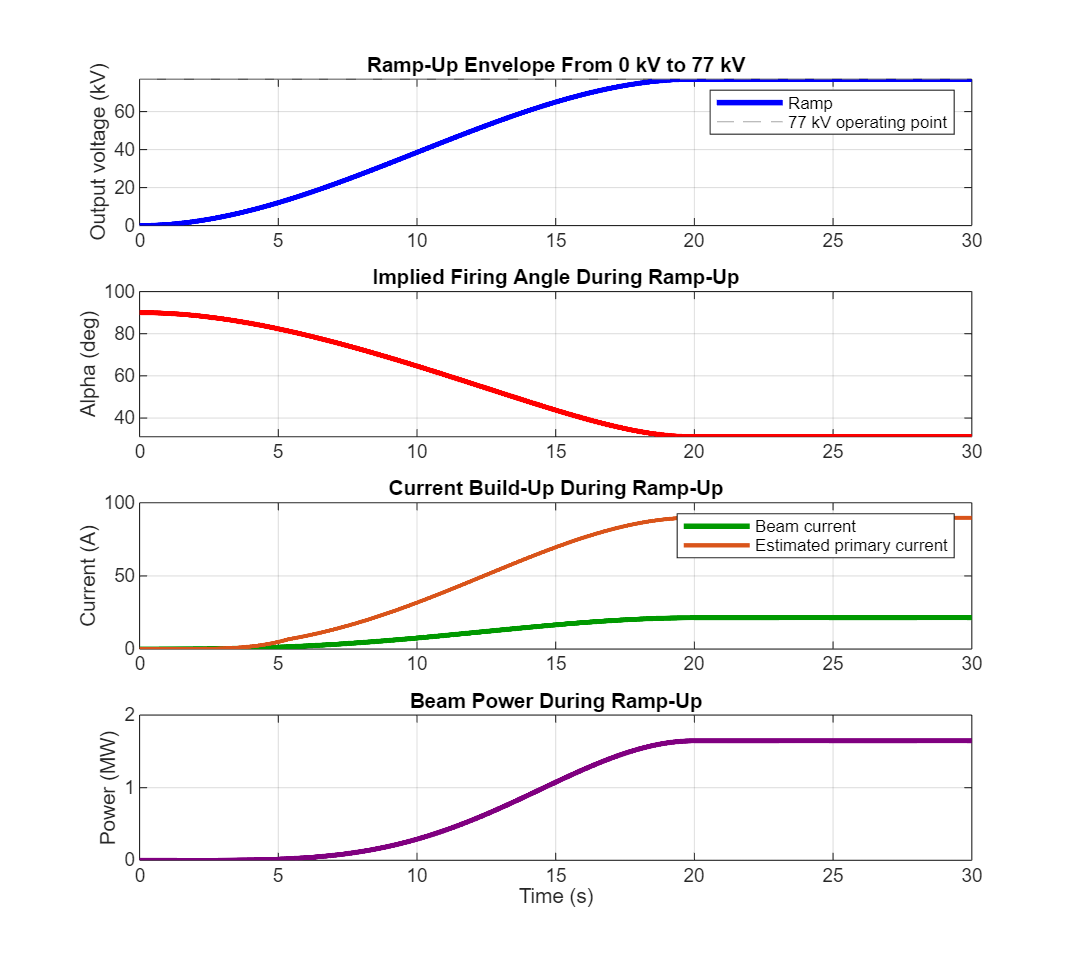


figure('Position', [100 100 1000 900]);
subplot(4,1,1);
plot(t_ramp, vdc_ramp/1e3, 'b', 'LineWidth', 2.5); hold on;
yline(sys.vdc_nominal/1e3, '--', 'Color', [0.5 0.5 0.5]);
title('Ramp-Up Envelope From 0 kV to 77 kV'); ylabel('Output voltage (kV)');
legend('Ramp','77 kV operating point'); grid on;

subplot(4,1,2);
plot(t_ramp, alpha_ramp, 'r', 'LineWidth', 2.5);
title('Implied Firing Angle During Ramp-Up'); ylabel('Alpha (deg)'); grid on;

subplot(4,1,3);
plot(t_ramp, beam_current_ramp, 'Color', [0 0.6 0], 'LineWidth', 2.5); hold on;
plot(t_ramp, primary_current_ramp, 'Color', [0.85 0.33 0.1], 'LineWidth', 2);
title('Current Build-Up During Ramp-Up'); ylabel('Current (A)');
legend('Beam current','Estimated primary current'); grid on;

subplot(4,1,4);
plot(t_ramp, beam_power_ramp, 'Color', [0.5 0 0.5], 'LineWidth', 2.5);
title('Beam Power During Ramp-Up'); xlabel('Time (s)'); ylabel('Power (MW)'); grid on;

## 4B. Representative B118 Monitoring Channels

Four Building 118 monitoring channels used for troubleshooting: 1. HVPS output voltage 2. HVPS output current 3. Transformer 1 phase current 4. Inductor 2 diagnostic voltage

Two views: (a) long time-base through ramp-up, (b) short time-base near steady operation showing waveform character. These are engineering reconstructions, not archived measurements.

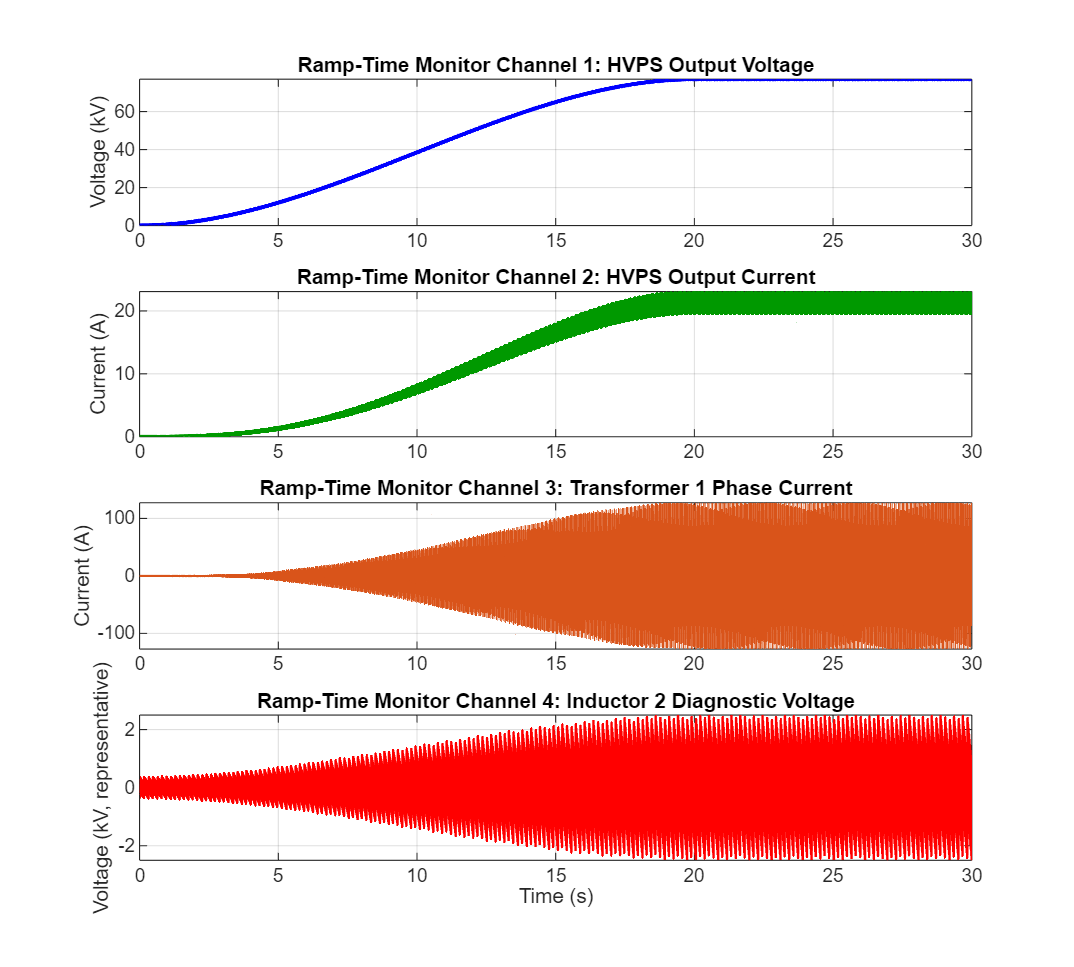

ripple_pp_frac_local    = 1.0 - cos(15*DEG);
f_ripple_hz_local       = 12 * sys.f_line_hz;
f0_hz_local             = 1/(2*pi*sqrt(1.07 * sys.cap_filter_f));
atten_ratio_local       = (f_ripple_hz_local / f0_hz_local)^2;
filtered_ripp_pp_local  = ripple_pp_frac_local * sys.vdc_nominal / atten_ratio_local;
nominal_beam_pwr_w      = sys.vdc_nominal * sys.idc_nominal;
primary_current_nominal = nominal_beam_pwr_w / (sys.v_t1_primary_ll_rms * sqrt(3) * 0.95);

% sawtooth helper
sawtooth_wave = @(t, f) 2*mod(t.*f, 1) - 1;

% Ramp-time monitor channels
mon_v_ramp = vdc_ramp + 0.5*filtered_ripp_pp_local .* cos(2*pi*f_ripple_hz_local.*t_ramp);

mon_i_ramp = beam_current_ramp + 0.08*max(beam_current_ramp,1e-9) .* ...
    cos(2*pi*f_ripple_hz_local.*t_ramp + pi/6);
mon_i_ramp = max(mon_i_ramp, 0);

phase_curr_base = primary_current_ramp .* sqrt(2);
mon_t1_ramp = phase_curr_base .* ( ...
    sin(2*pi*sys.f_line_hz.*t_ramp) ...
    + 0.10*sin(2*pi*11*sys.f_line_hz.*t_ramp) ...
    + 0.08*sin(2*pi*13*sys.f_line_hz.*t_ramp) );

ind2_envelope = 0.15 + 0.85*(vdc_ramp / sys.vdc_nominal);
mon_l2_ramp = 2.5e3 .* ind2_envelope .* sawtooth_wave(t_ramp, 12*sys.f_line_hz);

figure('Position', [100 100 1000 900]);
subplot(4,1,1);
plot(t_ramp, mon_v_ramp/1e3, 'b', 'LineWidth', 2); grid on;
title('Ramp-Time Monitor Channel 1: HVPS Output Voltage'); ylabel('Voltage (kV)');

subplot(4,1,2);
plot(t_ramp, mon_i_ramp, 'Color', [0 0.6 0], 'LineWidth', 2); grid on;
title('Ramp-Time Monitor Channel 2: HVPS Output Current'); ylabel('Current (A)');

subplot(4,1,3);
plot(t_ramp, mon_t1_ramp, 'Color', [0.85 0.33 0.1], 'LineWidth', 1.2); grid on;
title('Ramp-Time Monitor Channel 3: Transformer 1 Phase Current'); ylabel('Current (A)');

subplot(4,1,4);
plot(t_ramp, mon_l2_ramp/1e3, 'r', 'LineWidth', 1.2); grid on;
title('Ramp-Time Monitor Channel 4: Inductor 2 Diagnostic Voltage');
xlabel('Time (s)'); ylabel('Voltage (kV, representative)');

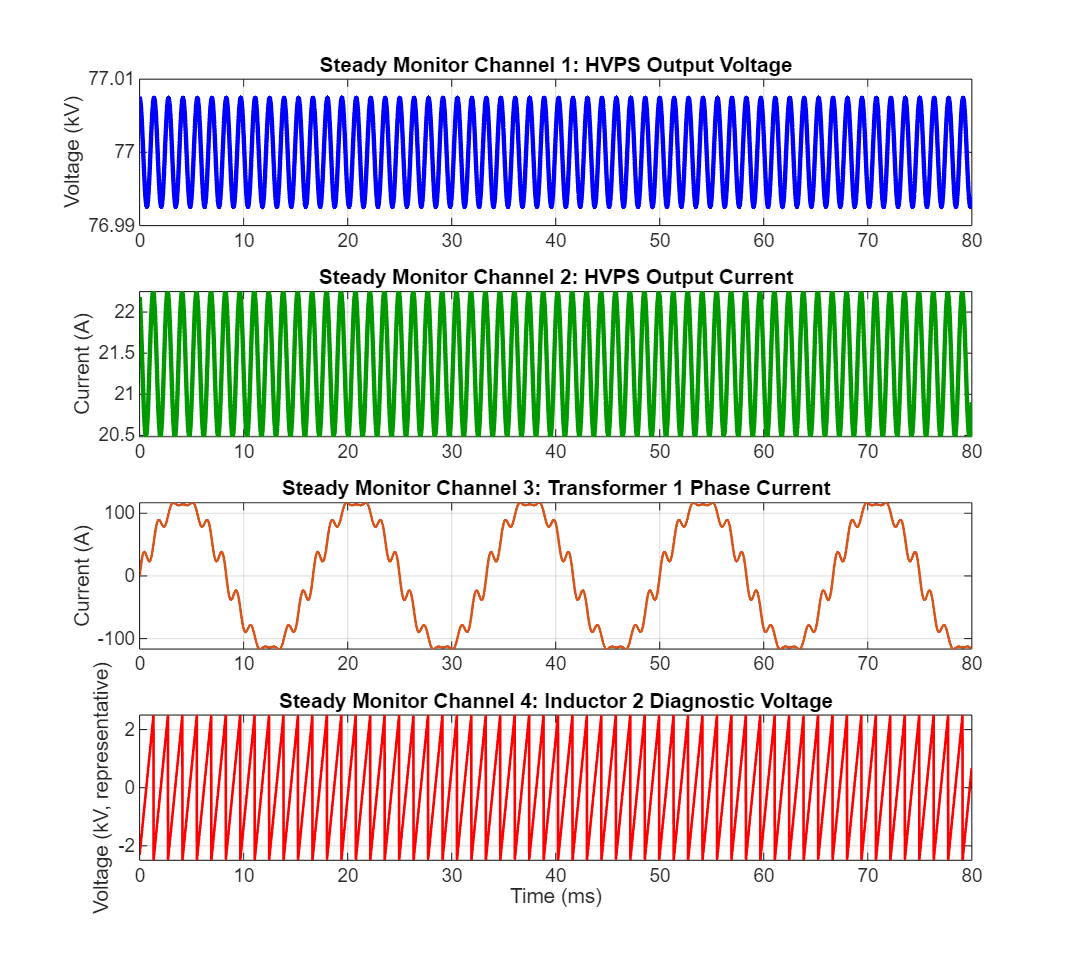


% --- Steady-state short time-base view ---
steady_win_s  = 0.080;
steady_samps  = 6000;
t_steady = linspace(0, steady_win_s, steady_samps);

vdc_steady = sys.vdc_nominal + 0.5*filtered_ripp_pp_local .* cos(2*pi*f_ripple_hz_local.*t_steady);

idc_steady = perveance .* max(vdc_steady,0).^1.5 + ...
    0.04*sys.idc_nominal .* cos(2*pi*f_ripple_hz_local.*t_steady + pi/8);

it1_steady = sqrt(2)*primary_current_nominal .* ( ...
    sin(2*pi*sys.f_line_hz.*t_steady) ...
    + 0.10*sin(2*pi*11*sys.f_line_hz.*t_steady) ...
    + 0.08*sin(2*pi*13*sys.f_line_hz.*t_steady) );

l2_steady = 2.5e3 .* sawtooth_wave(t_steady + alpha_nom/360/sys.f_line_hz, 12*sys.f_line_hz);

figure('Position', [100 100 1000 900]);
subplot(4,1,1);
plot(t_steady*1e3, vdc_steady/1e3, 'b', 'LineWidth', 2); grid on;
title('Steady Monitor Channel 1: HVPS Output Voltage'); ylabel('Voltage (kV)');

subplot(4,1,2);
plot(t_steady*1e3, idc_steady, 'Color', [0 0.6 0], 'LineWidth', 2); grid on;
title('Steady Monitor Channel 2: HVPS Output Current'); ylabel('Current (A)');

subplot(4,1,3);
plot(t_steady*1e3, it1_steady, 'Color', [0.85 0.33 0.1], 'LineWidth', 1.2); grid on;
title('Steady Monitor Channel 3: Transformer 1 Phase Current'); ylabel('Current (A)');

subplot(4,1,4);
plot(t_steady*1e3, l2_steady/1e3, 'r', 'LineWidth', 1.2); grid on;
title('Steady Monitor Channel 4: Inductor 2 Diagnostic Voltage');
xlabel('Time (ms)'); ylabel('Voltage (kV, representative)');

## 5. Load Model, Beam Perveance, and Power

The document models the klystron beam current with a Child-Langmuir style perveance law using approximately $1.0 \times 10^{-6}$ A/V$^{3/2}$:


$$I_{beam} = P_k\,V_{cathode}^{3/2}, \qquad P_k \approx 1.0 \times 10^{-6}\;\mathrm{A/V}^{3/2}$$



$$P_{beam} = V_{cathode}\,I_{beam}, \qquad R_{eff} = \frac{V_{cathode}}{I_{beam}}$$


This section reproduces the current, power, and effective impedance curves.

vdc_sweep = linspace(60e3, 90e3, 400);
beam_current = perveance .* vdc_sweep.^1.5;
beam_power_mw = vdc_sweep .* beam_current / 1e6;
eff_impedance_kohm = (vdc_sweep ./ beam_current) / 1e3;

% Sample table
sample_vdc = [60 65 70 72.08 77 80 85 90] * 1e3;
sample_idc = perveance .* sample_vdc.^1.5;
sample_tbl = table(sample_vdc'/1e3, sample_idc', ...
    (sample_vdc.*sample_idc)'/1e6, ((sample_vdc./sample_idc)/1e3)', ...
    'VariableNames', {'V_cathode_kV','I_beam_A','P_beam_MW','R_eff_kOhm'});
disp(sample_tbl);

    V_cathode_kV    I_beam_A    P_beam_MW    R_eff_kOhm
    ____________    ________    _________    __________

          60         14.697      0.88182       4.0825  
          65         16.572       1.0772       3.9223  
          70          18.52       1.2964       3.7796  
       72.08         19.352       1.3949       3.7247  
          77         21.367       1.6452       3.6037  
          80         22.627       1.8102       3.5355  
          85         24.782       2.1064         3.43  
          90             27         2.43       3.3333  



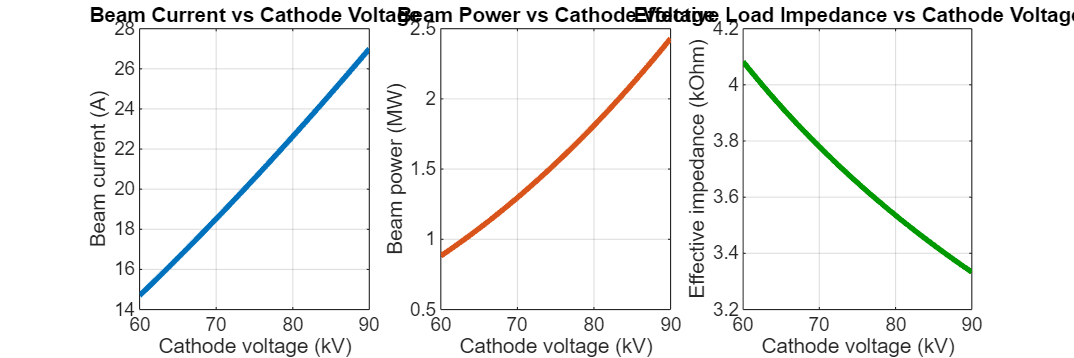


figure('Position', [100 100 1200 400]);
subplot(1,3,1);
plot(vdc_sweep/1e3, beam_current, 'LineWidth', 2.5); grid on;
title('Beam Current vs Cathode Voltage');
xlabel('Cathode voltage (kV)'); ylabel('Beam current (A)');

subplot(1,3,2);
plot(vdc_sweep/1e3, beam_power_mw, 'LineWidth', 2.5, 'Color', [0.85 0.33 0.1]); grid on;
title('Beam Power vs Cathode Voltage');
xlabel('Cathode voltage (kV)'); ylabel('Beam power (MW)');

subplot(1,3,3);
plot(vdc_sweep/1e3, eff_impedance_kohm, 'LineWidth', 2.5, 'Color', [0 0.6 0]); grid on;
title('Effective Load Impedance vs Cathode Voltage');
xlabel('Cathode voltage (kV)'); ylabel('Effective impedance (kOhm)');

## 6. Ripple Geometry and LC Filter Attenuation

The report connects the unfiltered ripple directly to the $30^\circ$ cosine arcs and then estimates attenuation using the reflected filter inductance and the $8\;\mu\mathrm{F}$ capacitor bank:


$$\frac{\Delta V_{pp}}{V_{max}} = 1 - \cos(15^\circ), \qquad f_{ripple} = 12\,f_{line} = 720\;\mathrm{Hz}$$



$$f_0 = \frac{1}{2\pi\sqrt{L_{eff}\,C}}, \qquad \text{Attenuation} = \left(\frac{f_{ripple}}{f_0}\right)^2$$


ripple_pp_fraction_geom = 1.0 - cos(15*DEG);
ripple_pp_nominal_volts = ripple_pp_fraction_geom * sys.vdc_nominal;

l_secondary_effective_h = 1.07;
f_ripple_hz = 12 * sys.f_line_hz;
f0_hz = 1 / (2*pi*sqrt(l_secondary_effective_h * sys.cap_filter_f));
attenuation_ratio = (f_ripple_hz / f0_hz)^2;
filtered_ripple_pp_volts  = ripple_pp_nominal_volts / attenuation_ratio;
filtered_ripple_rms_volts = filtered_ripple_pp_volts / (2*sqrt(2));

% Ripple summary table
ripple_metrics = {'Unfiltered ripple fraction'; 'Unfiltered ripple at 77 kV (Vpp)'; ...
    'Ripple frequency (Hz)'; 'Filter resonance (Hz)'; 'Attenuation ratio'; ...
    'Filtered ripple (Vpp)'; 'Filtered ripple (Vrms)'};
ripple_values = [ripple_pp_fraction_geom; ripple_pp_nominal_volts; f_ripple_hz; ...
    f0_hz; attenuation_ratio; filtered_ripple_pp_volts; filtered_ripple_rms_volts];
ripple_tbl = table(ripple_metrics, ripple_values, 'VariableNames', {'Metric','Value'});
disp(ripple_tbl);

                   Metric                    Value  
    ____________________________________    ________

    {'Unfiltered ripple fraction'      }    0.034074
    {'Unfiltered ripple at 77 kV (Vpp)'}      2623.7
    {'Ripple frequency (Hz)'           }         720
    {'Filter resonance (Hz)'           }      54.398
    {'Attenuation ratio'               }      175.19
    {'Filtered ripple (Vpp)'           }      14.977
    {'Filtered ripple (Vrms)'          }      5.2951



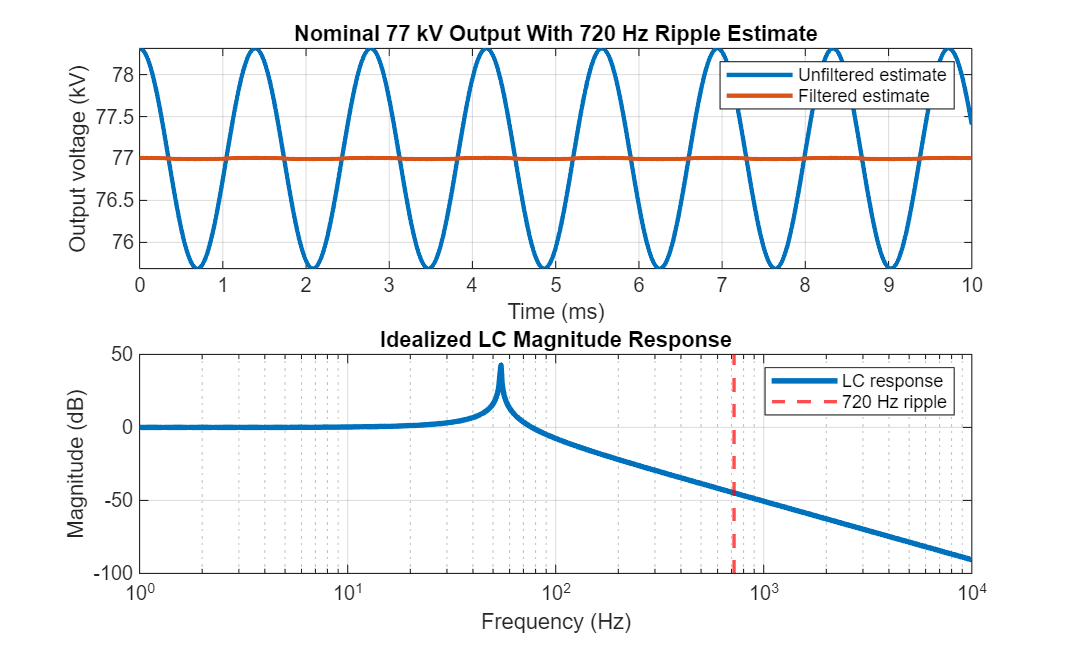


time_ms = linspace(0, 10, 4000);
unfiltered_ripple = sys.vdc_nominal + 0.5*ripple_pp_nominal_volts .* cos(2*pi*f_ripple_hz.*time_ms/1e3);
filtered_ripple   = sys.vdc_nominal + 0.5*filtered_ripple_pp_volts .* cos(2*pi*f_ripple_hz.*time_ms/1e3);

freq = logspace(0, 4, 800);
lc_gain = 1.0 ./ sqrt((1 - (freq/f0_hz).^2).^2 + 1e-12);

figure('Position', [100 100 1000 600]);
subplot(2,1,1);
plot(time_ms, unfiltered_ripple/1e3, 'LineWidth', 2); hold on;
plot(time_ms, filtered_ripple/1e3, 'LineWidth', 2);
title('Nominal 77 kV Output With 720 Hz Ripple Estimate');
xlabel('Time (ms)'); ylabel('Output voltage (kV)');
legend('Unfiltered estimate','Filtered estimate'); grid on;

subplot(2,1,2);
semilogx(freq, 20*log10(lc_gain), 'LineWidth', 2.5); hold on;
xline(f_ripple_hz, '--r', 'LineWidth', 1.5);
title('Idealized LC Magnitude Response');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
legend('LC response','720 Hz ripple'); grid on;

## 7. Protection Energy and Discharge Models

The analytical section distinguishes between total capacitor stored energy and the simplified RC branch discharge through the $500\;\Omega$ isolation path. It also quantifies primary inductor energy and the cable-inductor current slew limit:


$$E_C = \frac{1}{2}C\,V^2, \qquad E_L = \frac{1}{2}L\,I^2$$



$$i(t) = \frac{V_0}{R}\,e^{-t/\tau}, \qquad \tau = R\,C$$



$$E_{released}(t) = E_C\left(1 - e^{-2t/\tau}\right), \qquad \frac{di}{dt}\bigg|_{max} = \frac{V_0}{L_{cable}}$$


c_filter = sys.cap_filter_f;
r_iso    = sys.isolation_res_ohm;
tau_rc_s = r_iso * c_filter;
e_cap_j  = 0.5 * c_filter * sys.vdc_nominal^2;
i_branch_peak_a = sys.vdc_nominal / r_iso;

times_s = [1e-6, 10e-6, 0.1e-3, 1e-3, 2e-3, tau_rc_s];
i_branch   = i_branch_peak_a .* exp(-times_s / tau_rc_s);
e_released = e_cap_j .* (1 - exp(-2*times_s / tau_rc_s));

power_estimate_w = sys.vdc_measured * sys.idc_measured;
i_primary_operating_a   = power_estimate_w / (sys.v_t1_primary_ll_rms * sqrt(3) * 0.95);
e_inductor_operating_j  = 0.5 * sys.inductor_primary_h * i_primary_operating_a^2;
e_inductor_rated_j      = 0.5 * sys.inductor_primary_h * sys.inductor_primary_rated_a^2;
di_dt_limit_a_per_us    = (sys.vdc_nominal / sys.cable_inductor_h) / 1e6;
i2t_estimate = ((sys.vdc_nominal / r_iso)^2) * (tau_rc_s / 2);

% Protection summary table
prot_tbl = table(times_s'*1e3, i_branch', e_released', 100*e_released'/e_cap_j, ...
    'VariableNames', {'Time_ms','RC_branch_current_A','Released_energy_J','Released_energy_pct'});
disp(prot_tbl);

    Time_ms    RC_branch_current_A    Released_energy_J    Released_energy_pct
    _______    ___________________    _________________    ___________________

     0.001           153.96                11.855               0.049988      
      0.01           153.62                118.28                0.49875      
       0.1            150.2                1156.6                 4.8771      
         1           119.94                9331.5                 39.347      
         2           93.406                 14991                 63.212      
         4           56.653                 20506                 86.466      



fprintf('Capacitor stored energy at 77 kV: %.1f J\n', e_cap_j);

Capacitor stored energy at 77 kV: 23716.0 J


fprintf('Initial RC branch current: %.1f A\n', i_branch_peak_a);

Initial RC branch current: 154.0 A


fprintf('Inductor energy at rated 85 A: %.1f J per inductor\n', e_inductor_rated_j);

Inductor energy at rated 85 A: 1083.8 J per inductor


fprintf('Estimated primary current at measured operating point: %.1f A\n', i_primary_operating_a);

Estimated primary current at measured operating point: 68.0 A


fprintf('Inductor energy at measured operating point: %.1f J per inductor\n', e_inductor_operating_j);

Inductor energy at measured operating point: 693.3 J per inductor


fprintf('Cable inductor current slew limit: %.1f A/us\n', di_dt_limit_a_per_us);

Cable inductor current slew limit: 385.0 A/us


fprintf('Lumped RC I^2 t estimate: %.1f A^2 s\n', i2t_estimate);

Lumped RC I^2 t estimate: 47.4 A^2 s


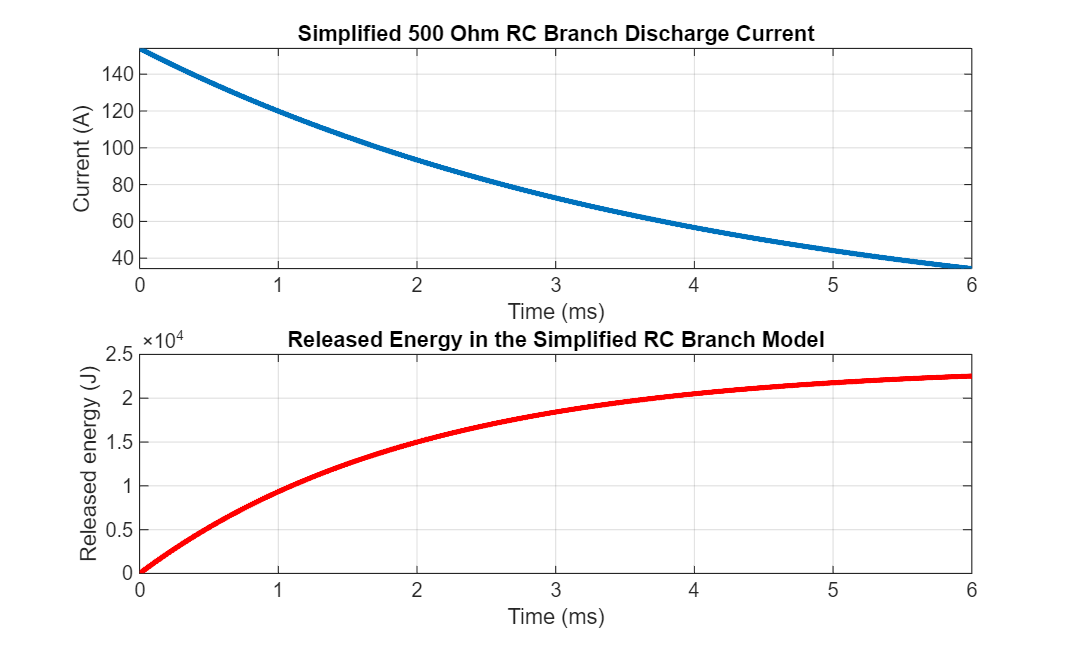


t_discharge_ms = linspace(0, 6, 2500);
current_discharge = i_branch_peak_a .* exp(-(t_discharge_ms/1e3) / tau_rc_s);
energy_discharge  = e_cap_j .* (1 - exp(-2*(t_discharge_ms/1e3) / tau_rc_s));

figure('Position', [100 100 1000 600]);
subplot(2,1,1);
plot(t_discharge_ms, current_discharge, 'LineWidth', 2.5); grid on;
title('Simplified 500 Ohm RC Branch Discharge Current');
xlabel('Time (ms)'); ylabel('Current (A)');

subplot(2,1,2);
plot(t_discharge_ms, energy_discharge, 'r', 'LineWidth', 2.5); grid on;
title('Released Energy in the Simplified RC Branch Model');
xlabel('Time (ms)'); ylabel('Released energy (J)');

## 8. Power Factor and Harmonic Content

The report uses displacement power factor $\cos(\alpha)$ multiplied by an idealized 12-pulse distortion factor of about 0.9886:


$$PF_{true} = \cos(\alpha)\times 0.9886$$


The dominant non-cancelled harmonics for a 12-pulse rectifier are orders $n = 12k \pm 1$ (i.e. 11, 13, 23, 25, 35, 37):


$$\mathrm{THD} = \sqrt{\sum_{n}\left(\frac{1}{n}\right)^2}$$


pf_curve = cosd(alpha_deg_vec) .* sys.power_factor_distortion_12pulse;

% harmonic_orders_12pulse
harmonics = [];
for n = 2:37
    if n > 1 && (mod(n,12) == 1 || mod(n,12) == 11)
        harmonics = [harmonics, n]; %#ok<AGROW>
    end
end
harmonic_magnitude = 1.0 ./ harmonics;
thd_estimate = sqrt(sum(harmonic_magnitude.^2));

harm_tbl = table(harmonics', harmonic_magnitude', (harmonics*sys.f_line_hz)', ...
    'VariableNames', {'Harmonic_order','Relative_magnitude','Frequency_Hz'});
disp(harm_tbl);

    Harmonic_order    Relative_magnitude    Frequency_Hz
    ______________    __________________    ____________

          11               0.090909              660    
          13               0.076923              780    
          23               0.043478             1380    
          25                   0.04             1500    
          35               0.028571             2100    
          37               0.027027             2220    



fprintf('Idealized THD estimate through 37th harmonic: %.2f%%\n', 100*thd_estimate);

Idealized THD estimate through 37th harmonic: 13.86%


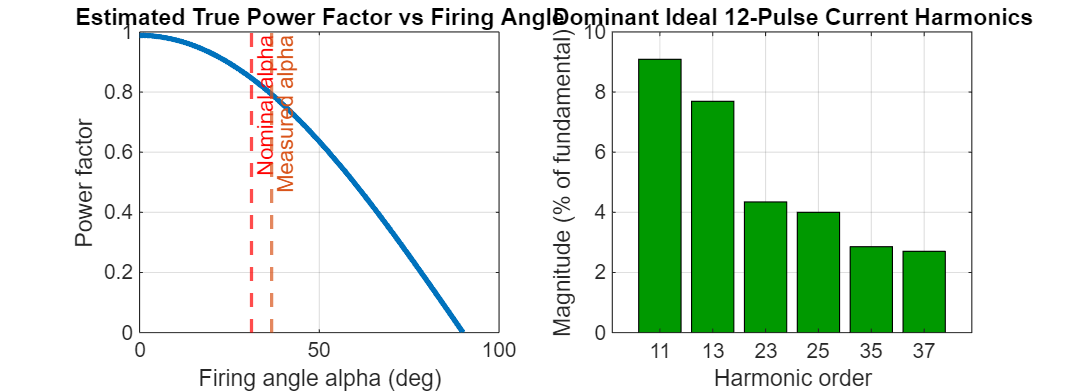


figure('Position', [100 100 1100 400]);
subplot(1,2,1);
plot(alpha_deg_vec, pf_curve, 'LineWidth', 2.5); hold on;
xline(alpha_nom, '--r', 'Nominal alpha', 'LineWidth', 1.5);
xline(alpha_meas, '--', 'Color', [0.85 0.33 0.1], 'Label', 'Measured alpha', 'LineWidth', 1.5);
title('Estimated True Power Factor vs Firing Angle');
xlabel('Firing angle alpha (deg)'); ylabel('Power factor'); grid on;

subplot(1,2,2);
bar(categorical(string(harmonics)), 100*harmonic_magnitude, 'FaceColor', [0 0.6 0]);
title('Dominant Ideal 12-Pulse Current Harmonics');
xlabel('Harmonic order'); ylabel('Magnitude (% of fundamental)'); grid on;

## 9. Consolidated Design Summary

This final section gathers the main numerical outputs so the notebook can serve as a quick engineering reference alongside the report.

summary_params = {
    '12-pulse DC coefficient';
    'Secondary LL voltage for 90 kV max';
    'Transformer turns ratio';
    'Nominal alpha at 77 kV';
    'Measured alpha at 72.08 kV';
    'Ripple frequency';
    'LC resonance estimate';
    'Unfiltered ripple fraction';
    'Filtered ripple at 77 kV (Vpp)';
    'Capacitor stored energy at 77 kV';
    'Cable current slew limit';
    'Idealized PF at nominal alpha';
};

summary_values = [
    6*sqrt(2)/pi;
    sys.v_secondary_ll_rms / 1e3;
    turns_ratio;
    alpha_nom;
    alpha_meas;
    f_ripple_hz;
    f0_hz;
    ripple_pp_fraction_geom;
    filtered_ripple_pp_volts;
    e_cap_j;
    di_dt_limit_a_per_us;
    cosd(alpha_nom) * sys.power_factor_distortion_12pulse;
];

summary_units = {
    'Vdc / V_LL';
    'kV RMS';
    ':1';
    'deg';
    'deg';
    'Hz';
    'Hz';
    'fraction';
    'Vpp';
    'J';
    'A/us';
    'fraction';
};

summary_tbl = table(summary_params, summary_values, summary_units, ...
    'VariableNames', {'Parameter','Value','Units'});
disp(summary_tbl);

                  Parameter                    Value          Units     
    ______________________________________    ________    ______________

    {'12-pulse DC coefficient'           }      2.7009    {'Vdc / V_LL'}
    {'Secondary LL voltage for 90 kV max'}        33.3    {'kV RMS'    }
    {'Transformer turns ratio'           }       2.664    {':1'        }
    {'Nominal alpha at 77 kV'            }      31.117    {'deg'       }
    {'Measured alpha at 72.08 kV'        }      36.735    {'deg'       }
    {'Ripple frequency'                  }         720    {'Hz'        }
    {'LC resonance estimate'             }      54.398    {'Hz'        }
    {'Unfiltered ripple fraction'        }    0.034074    {'fraction'  }
    {'Filtered ripple at 77 kV (Vpp)'    }      14.977    {'Vpp'       }
    {'Capacitor stored energy at 77 kV'  }       23716    {'J'         }
    {'Cable current s